# **Fundamentals of Robotics**

**Introduction to Robotics Modeling and Control**

clear;
close all;
format compact;

## Forward Kinematics: Denavit-Hartenberg Convention

#### EXAMPLE 1. Two Link Planar Robot Manipulator

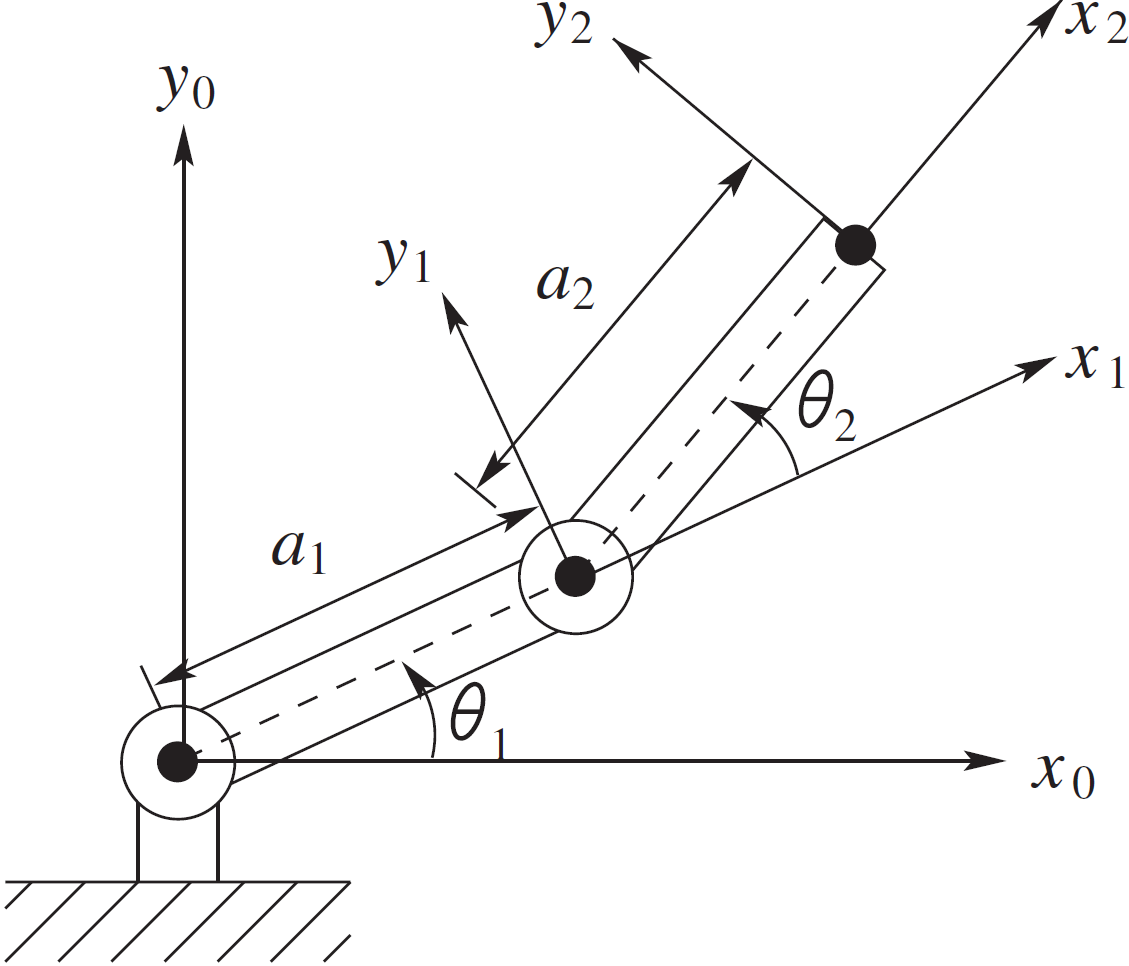

**DH Parameters Table:**

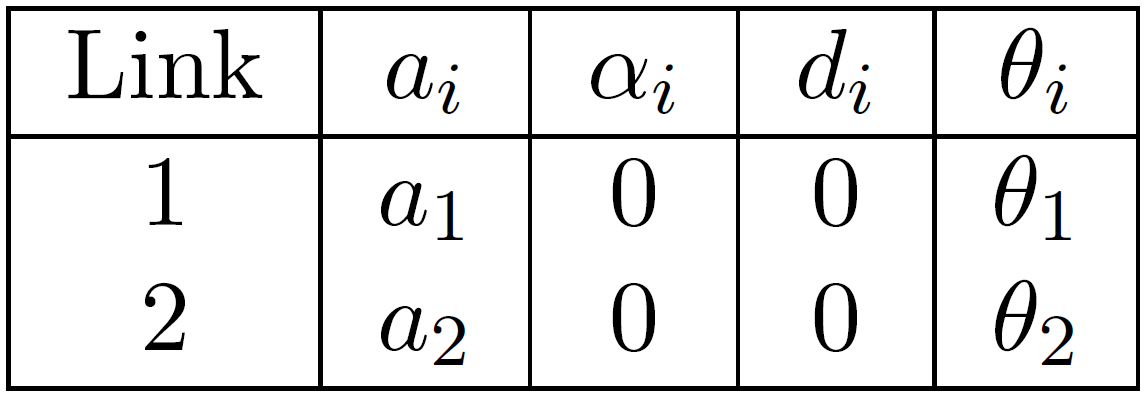

link1 = RevoluteLink(0, 1.25, 0, 0, 'name', 'link1');   % LINK1:    d=0, a=1, alpha=0, *theta1 + offset=0
link2 = RevoluteLink(0, 1.25, 0, 0, 'name', 'link2');   % LINK2:    d=0, a=1, alpha=0, *theta2 + offset=0

% Serial Link Manipulator
% 2-DOF (RR) Planar Robot
robot = SerialLinkManipulator([link1, link2], 'name', '2-DOF RR Planar Robot');

theta1 =-45;
theta2 =45;

robot.links(1).theta = deg2rad(theta1);
robot.links(2).theta = deg2rad(theta2);

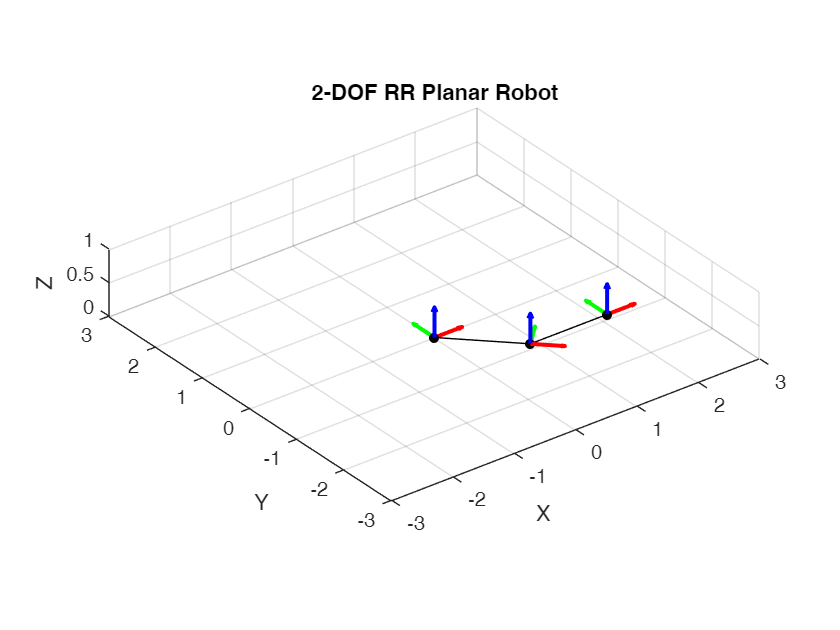

figure;
hold on;
plot([robot.jointPose(1,:), robot.x(1)], [robot.jointPose(2,:), robot.x(2)], 'k-');
plotHomogFrames(robot.homogtf, 'Scale', 0.5, 'ArrowStyle', 'arrow'); 

title(robot.name);
xlim([-3, 3]); 
ylim([-3, 3]); 
zlim([0, 1]);

#### EXAMPLE 2. Three-Link Cylindrical Manipulator

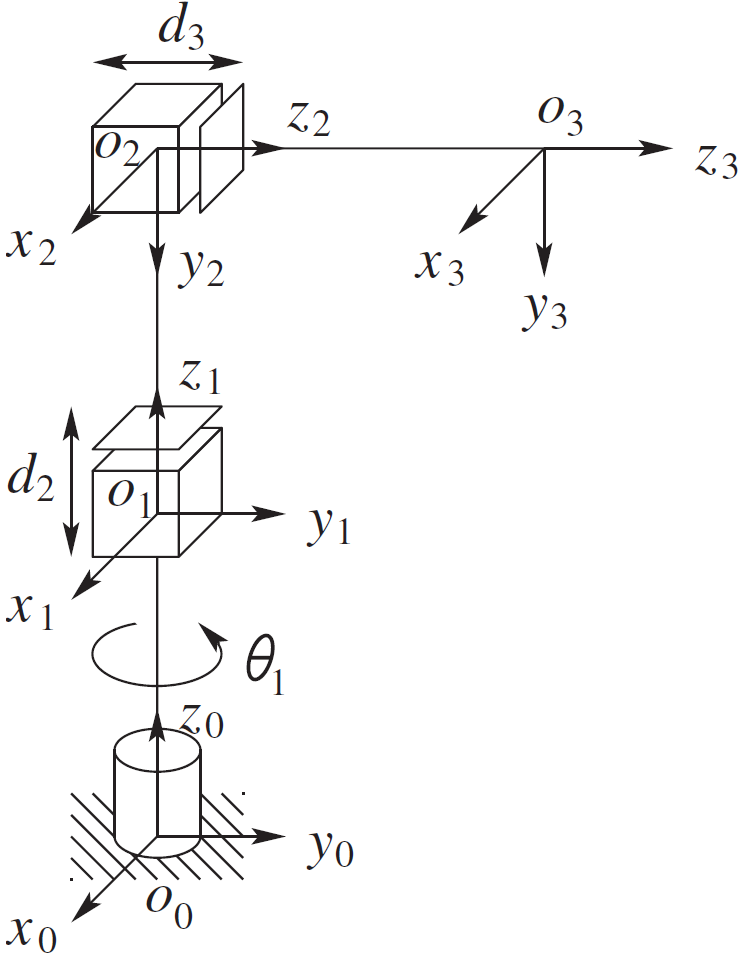

**DH Parameters Table:**

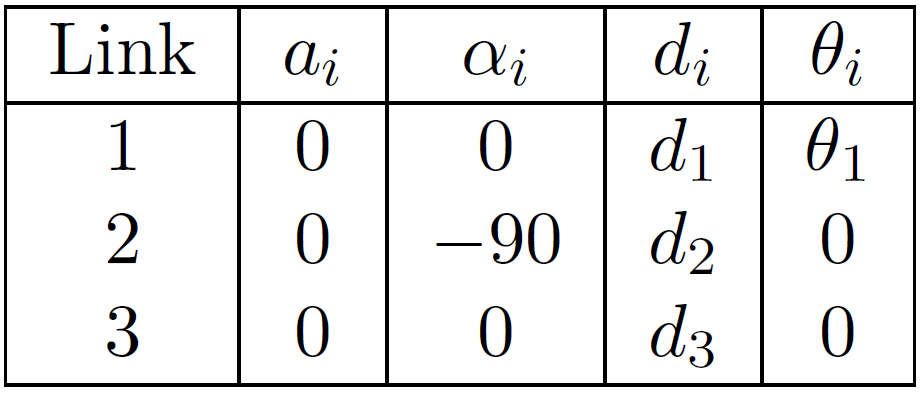

l1 = Link([0, 1, 0, 0]);
l2 = Link([0, 0, 0, -pi/2], 'type', 'prismatic');
l3 = Link([0, 0, 0, 0], 'type', 'prismatic');

% Three-Link Cylindrical Manipulator
robot = SerialLinkManipulator([l1, l2, l3], 'name', '3-DOF RPP Cylindrical Manipulator');

theta1 =30;
d2 =1.5;
d3 =1;

robot.links(1).theta = deg2rad(theta1);
robot.links(2).d = d2;
robot.links(3).d = d3;

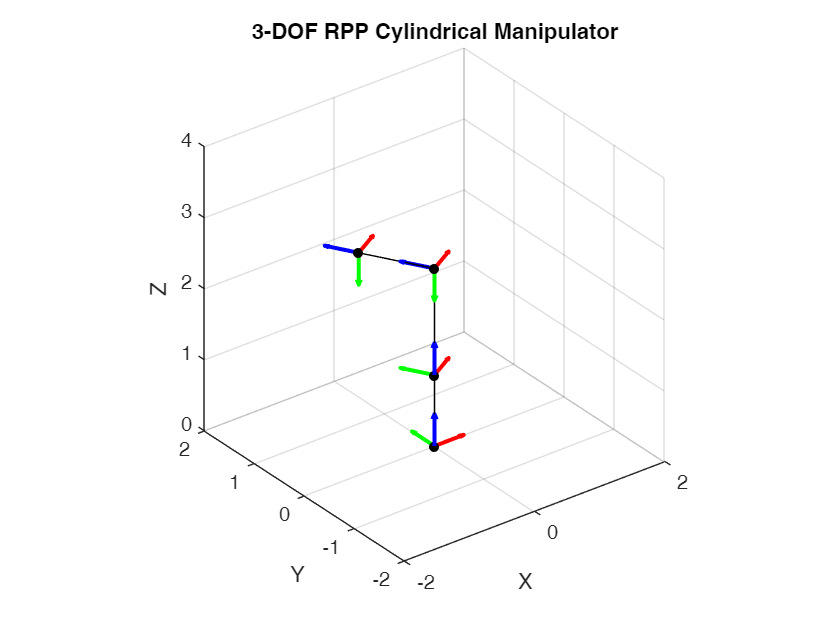

figure;
hold on;
plot3([robot.jointPose(1,:), robot.x(1)], [robot.jointPose(2,:), robot.x(2)], [robot.jointPose(3,:), robot.x(3)], 'k-');
plotHomogFrames(robot.homogtf, 'Scale', 0.5, 'ArrowStyle', 'arrow'); 

title(robot.name);
xlim([-2, 2]); 
ylim([-2, 2]); 
zlim([0, 4]);

#### EXAMPLE 3. The Spherical Wrist

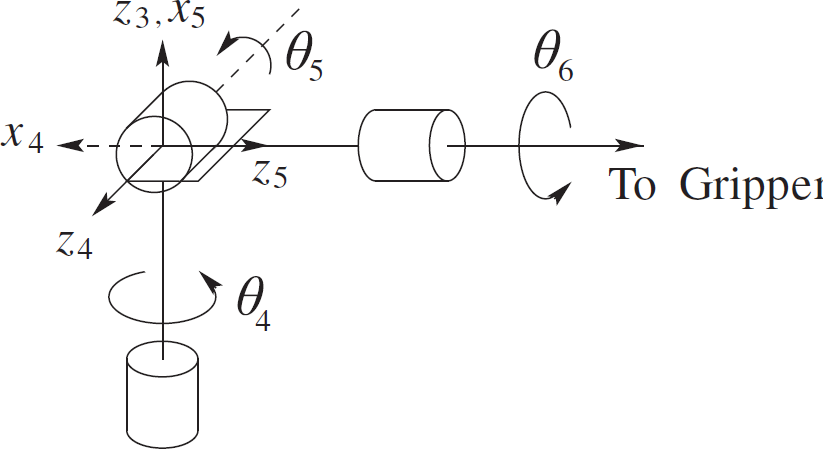

**DH Parameters Table:**

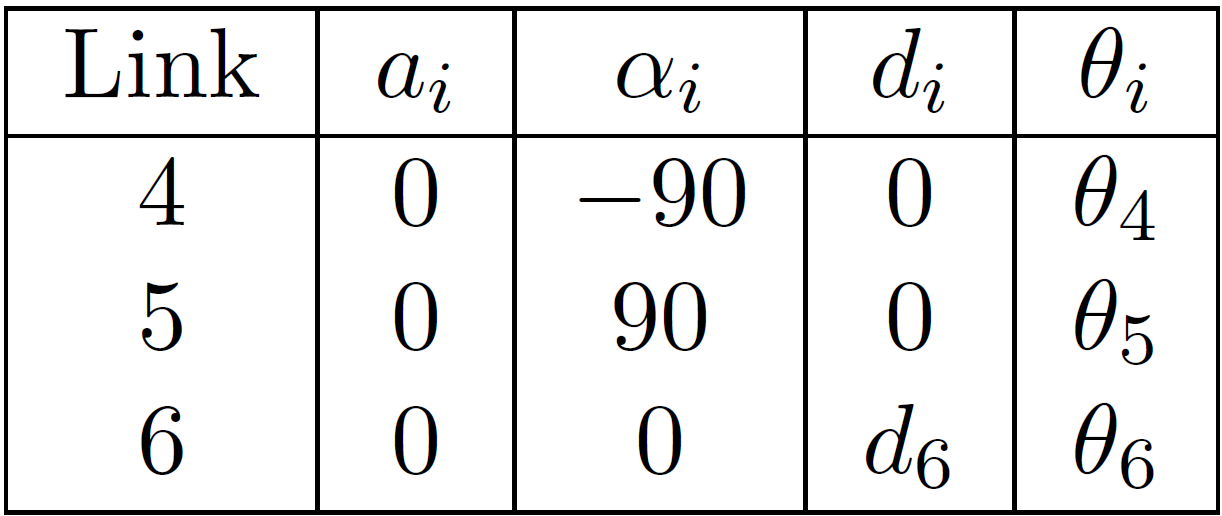

link1 = RevoluteLink(0, 0, -pi/2, 0, 'name', 'link1');  % LINK1:    d=0, a=0, alpha=-90, *theta1 + offset=0
link2 = RevoluteLink(0, 0, pi/2, 0, 'name', 'link2');   % LINK2:    d=0, a=0, alpha=90, *theta2 + offset=0
link3 = RevoluteLink(1, 0, 0, 0, 'name', 'link2');      % LINK2:    d=1, a=0, alpha=0, *theta3 + offset=0

% Serial Link Manipulator
% 2-DOF (RR) Planar Robot
robot = SerialLinkManipulator([link1, link2, link3], 'name', 'Spherical Wrist');

theta1 =-45;
theta2 =45;
theta3 =-45;

robot.links(1).theta = deg2rad(theta1);
robot.links(2).theta = deg2rad(theta2);
robot.links(3).theta = deg2rad(theta3);

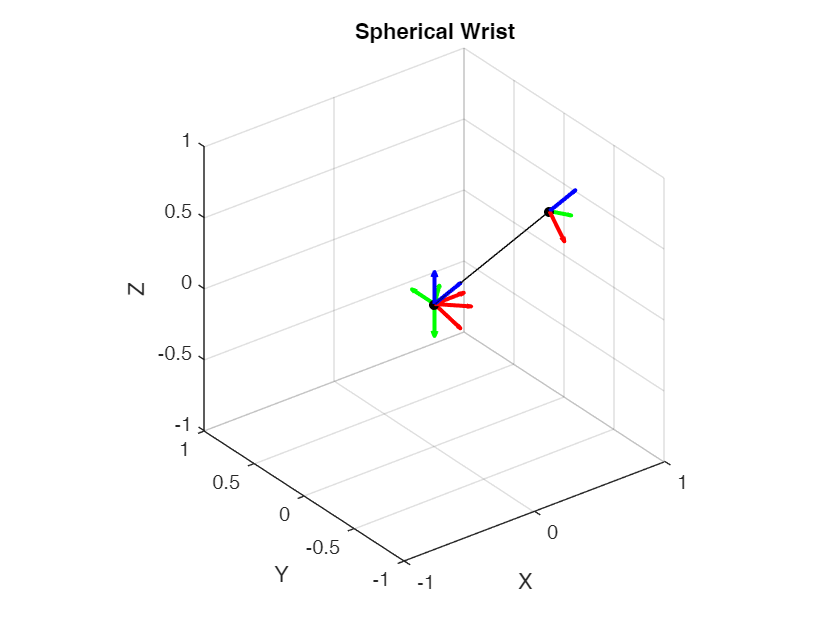

figure;
hold on;
plot3([robot.jointPose(1,:), robot.x(1)], [robot.jointPose(2,:), robot.x(2)], [robot.jointPose(3,:), robot.x(3)], 'k-');
plotHomogFrames(robot.homogtf, 'Scale', 0.25, 'ArrowStyle', 'arrow'); 

title(robot.name);
xlim([-1, 1]); 
ylim([-1, 1]); 
zlim([-1, 1]);

#### EXAMPLE 4. SCARA Robot

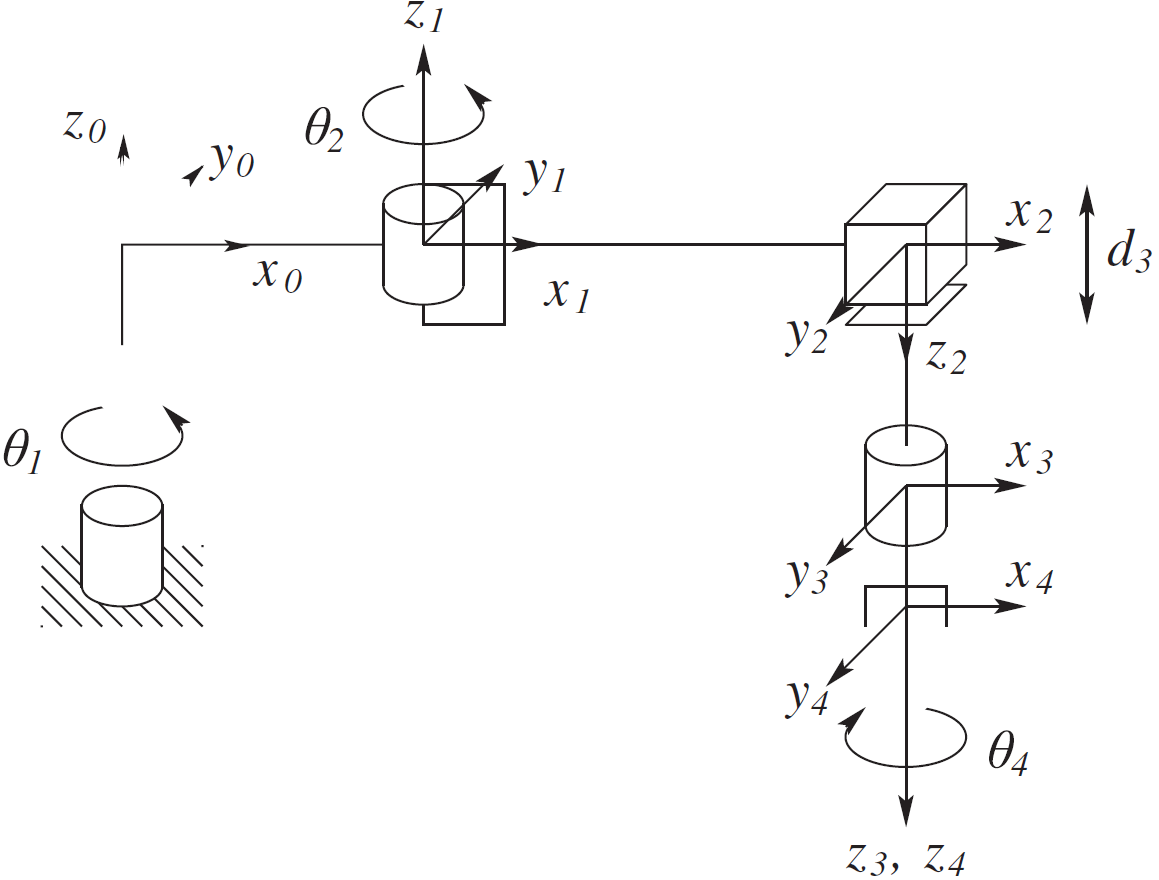

**DH Parameters Table:**

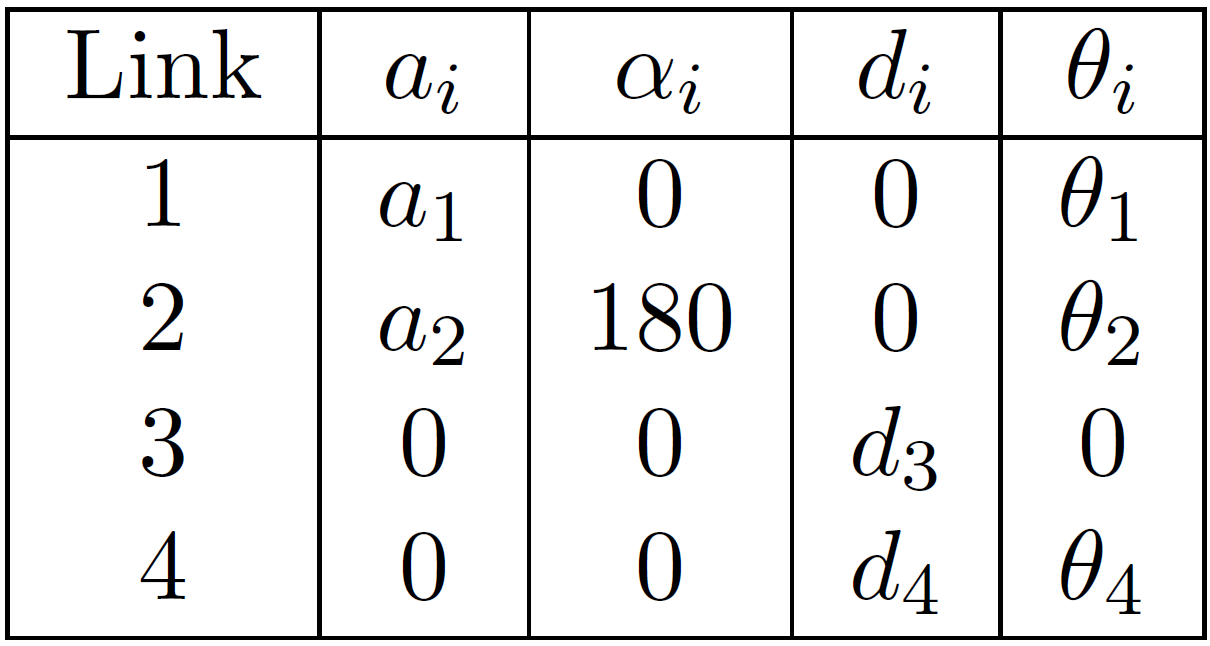

l1 = Link([0, 0, 0.5, 0]);
l2 = Link([0, 0, 0.5, pi]);
l3 = Link([0, 0, 0, 0], 'type', 'prismatic');
l4 = Link([0, 0.25, 0, 0]);

% Three-Link Cylindrical Manipulator
robot = SerialLinkManipulator([l1, l2, l3, l4], 'name', 'SCARA Robot');

theta1 =0;
theta2 =-60;
d3 =0.5;
theta4 =0;

robot.links(1).theta = deg2rad(theta1);
robot.links(2).theta = deg2rad(theta2);
robot.links(3).d = d3;
robot.links(4).theta = deg2rad(theta4);

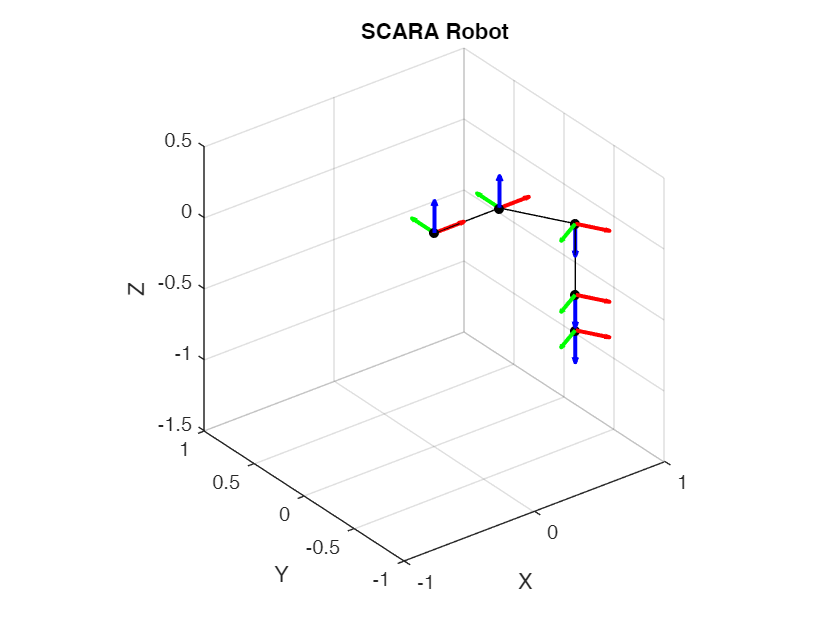

figure;
hold on;
plot3([robot.jointPose(1,:), robot.x(1)], [robot.jointPose(2,:), robot.x(2)], [robot.jointPose(3,:), robot.x(3)], 'k-');
plotHomogFrames(robot.homogtf, 'Scale', 0.25, 'ArrowStyle', 'arrow'); 

title(robot.name);
xlim([-1, 1]); 
ylim([-1, 1]); 
zlim([-1.5, 0.5]);